tspan=0:0.2:10;
za=fzero(  @res, -50     ) %solve for the true za 

za = -43.1190

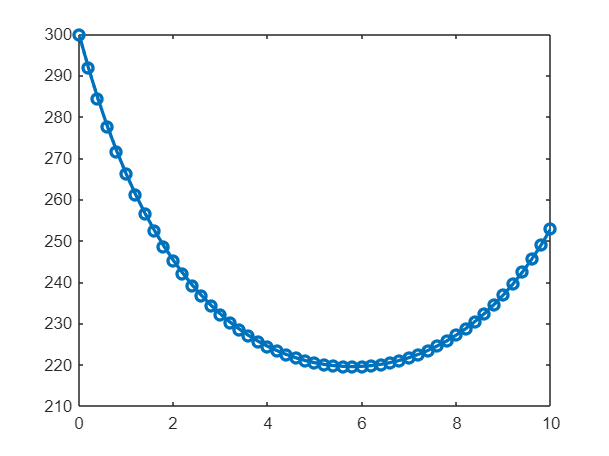

[x,T]=ode45(@dydxn, tspan, [ 300, za  ]); 
figure
plot(  x, T(:,1), '-o','linewidth', 2    );%plot temperature vs. x


k2 = find(x==2)%finds the index when x=2

k2 = 11

Tx2=T(k2,1) %Temp at x = 2

Tx2 = 245.2362


k8 = find(x==8)%finds the index when x=8

k8 = 41

Tx8=T(k8,1) %Temp at x = 8

Tx8 = 227.2137

function dy=dydxn(x,y)%function for the 2 ODEs
%nonlinear heat conduction with convection & radiation on bar
dy=[y(2);-0.05*(200-y(1))-2.7e-9*(1.6e9-y(1)^4)];
end

function r=res(za)  %residual function
%residual for nonlinear radiation
[x,y]=ode45(@dydxn, [0:0.2:10], [300 za ]);
r=   y(end, 2) - 20        ; %right side dT/dx = 20
end